# DSZOB, cvičenie 3.

## **Zadanie:**

## **Úloha 1 **

Vygenerujte si nasledujúce signály podľa predchádzajúcich cvičení:

- jednoduchý signál

- zložený signál (z troch jednoduchých signálov)

- jednoduchý signál so zníženou vzorkovacou frekvenciou s porušením Nyquistovho teorému

Pre vytvorené signály:

- Z daných signálov vyberte vhodnú vzorku 512 hodnôt, vypočítajte a vizualizujte Diskrétnu Fourierovu transformáciu podľa definície.

- Následne vypočítajte a vizualizujte príslušnú inverznú Fourierovu transformáciu. Aký je výstup? 

- Výpočet DFT a IDFT implementujte ako samostatné funkcie. 

- Výstup DFT vizualizujte, pričom spektrálne indexy prevediete na Hz. (fftshift a druhá polovica výstupu; prepočet od 0 do Fs/2 Hz, index-1)

- K signálom pripočítajte konštantnú hodnotu  (DC komponentu). Vypočítajte DFT a vizualizujte (originál výstup a aj pomocou fftshift) . Kde je možné vo vypočítanej DFT DC komponentu identifikovať?

## Pomôcka (definícia):

- počet prvkov vo vektore

- index spektrálnych koeficientov

- index vzorku vo vstupnom vektore (číslicový signál o dĺžke N)

## Pomôcka:

- pozor na názov funkcií

- fftshift()

- stem()

- abs()

- j

**Postup vhodne dokumentuje (Code/Text bloky)!**

**Pri vizualizácií zamedzte zobrazovaniu upozornení.**

## **Riešenie:**

## **Simple signals**

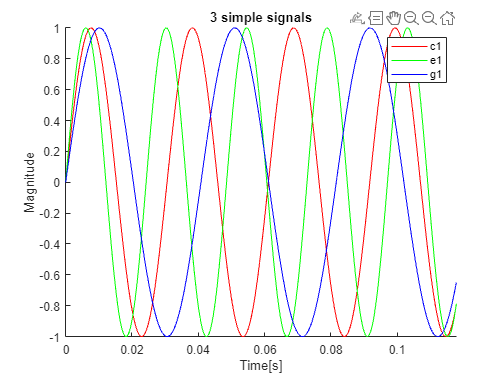

clear
frequency = 44100;
t = 3;
time_axis = 0:1/frequency:t;

c1 = 32.7;
e1 = 41.2;
g1 = 24.5;
c6= 1046.4;

frequency_1 = c1 * 2 * pi;
frequency_2 = e1 * 2 * pi;
frequency_3 = g1 * 2 * pi;
frequency_4 = c6* 2 * pi;
sig_1 = sin(time_axis * frequency_1);
sig_2 = sin(time_axis * frequency_2); 
sig_3 = sin(time_axis * frequency_3); 
sig_4 = sin(time_axis * frequency_4);

hold on
plot(time_axis, sig_1, "red");
plot(time_axis, sig_2, "green");
plot(time_axis, sig_3, "blue");
xlim([0,0.1])
xlabel("Time[s]");
ylabel("Magnitude");
title("3 simple signals");
legend("c1", "e1", "g1")
hold off

## **Composite signal**

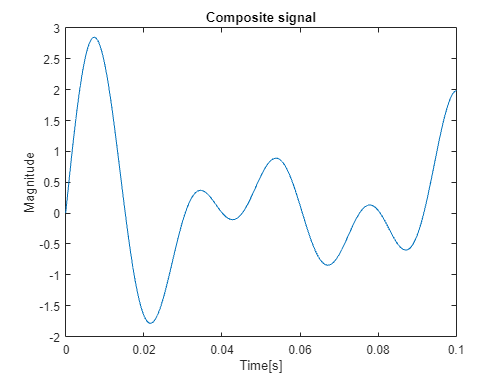

composite = sig_1 + sig_2 + sig_3;
plot(time_axis, composite);
title("Composite signal")
xlim([0, 0.1])
xlabel("Time[s]");
ylabel("Magnitude");

## **Broken Nyquist theorem signal**

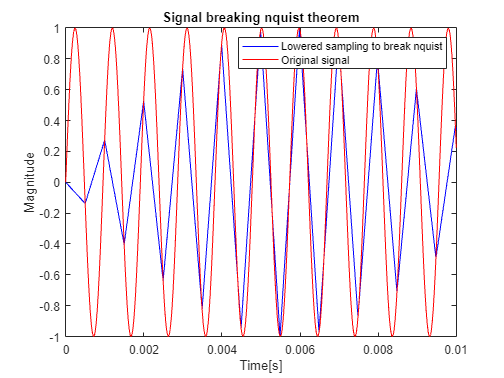

nquist_lim = round((frequency/ c6)/2);
sig_broken = downsample(sig_4, nquist_lim + 1);
time_axis_broken = downsample(time_axis, nquist_lim + 1);

plot(time_axis_broken, sig_broken, "blue"); hold on
plot(time_axis, sig_4, "red"); 

xlim([0,0.01])
title("Signal breaking nquist theorem");
xlabel("Time[s]");
ylabel("Magnitude");
legend("Lowered sampling to break nquist", "Original signal")
hold off

## Simple signal

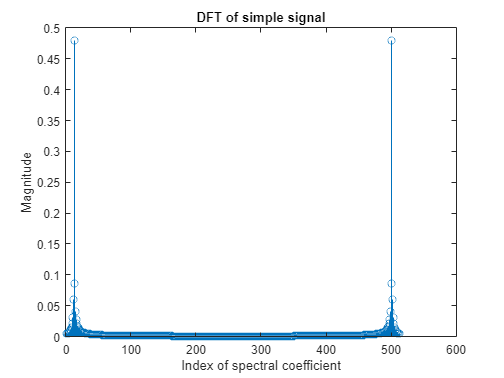

sig_4_dft = calculate_dft(sig_4(1:512));
stem(abs(sig_4_dft));
title("DFT of simple signal")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

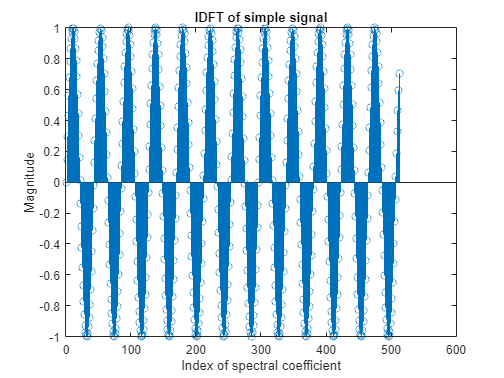

sig_4_idft = calculate_idft(sig_4_dft);
stem(real(sig_4_idft));
title("IDFT of simple signal")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

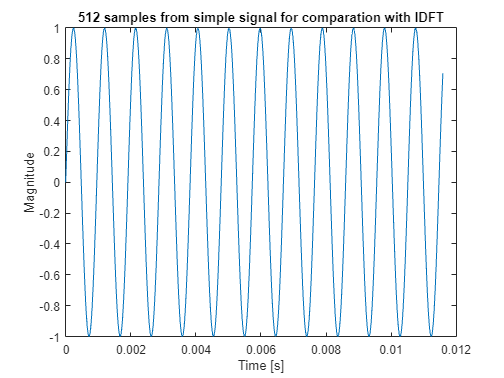

plot(time_axis(1:512), sig_4(1:512))
title("512 samples from simple signal for comparation with IDFT")
ylabel("Magnitude")
xlabel("Time [s]")

**Answer: **The result of inverse dft is the original signal, as shown with our visualizations

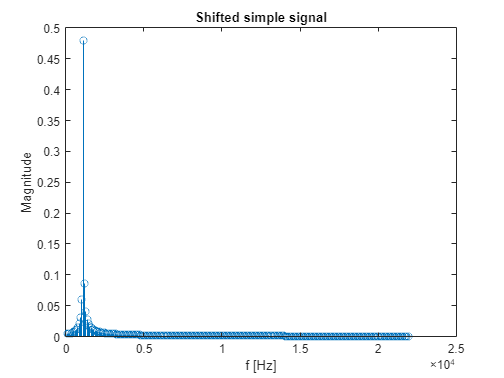

fq = ((1:256)*22000) / 257;
shifted_sig_4 = fftshift(abs(sig_4_dft));
stem(fq, shifted_sig_4(257:512));
title("Shifted simple signal")
ylabel("Magnitude")
xlabel("f [Hz]")

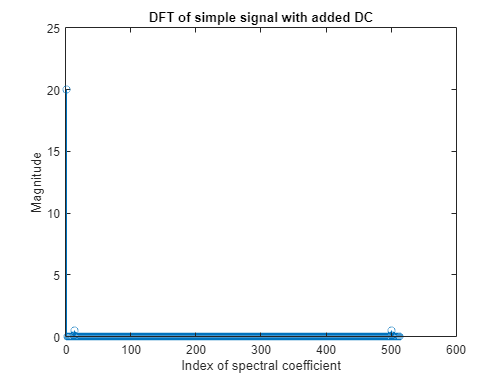

sig_4_dc = sig_4 + 20;
sig_4_dc_dft = calculate_dft(sig_4_dc(1:512));
stem(abs(sig_4_dc_dft))
title("DFT of simple signal with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

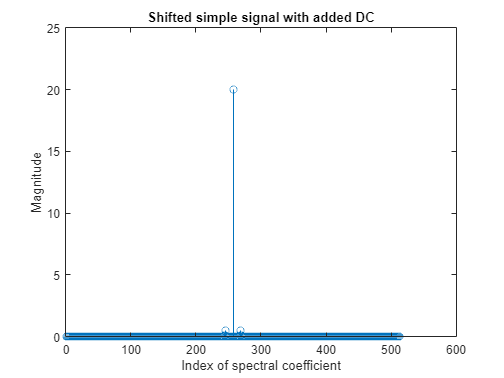

shifted_sig_4_dc = fftshift(abs(sig_4_dc_dft));
stem(shifted_sig_4_dc);
title("Shifted simple signal with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

**Answer: **Added scalar value can be seen on the graph as the highest value on the y-axis

## Composite signal

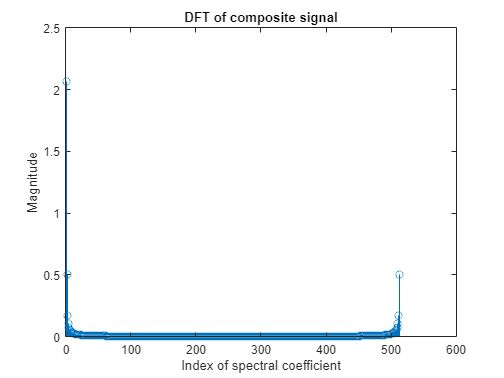

composite_dft = calculate_dft(composite(1:512));
stem(abs(composite_dft));
title("DFT of composite signal")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

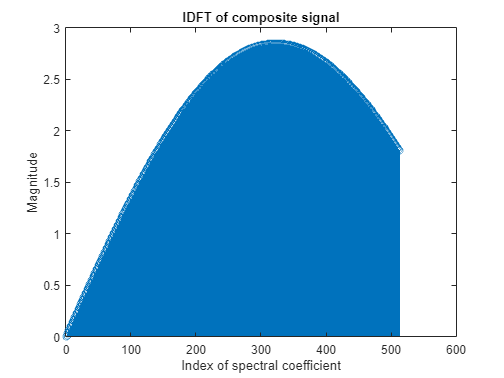

composite_idft = calculate_idft(composite_dft);
stem(real(composite_idft));
title("IDFT of composite signal")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

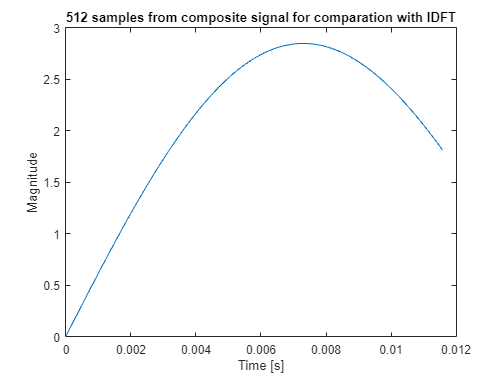

plot(time_axis(1:512), composite(1:512))
title("512 samples from composite signal for comparation with IDFT")
ylabel("Magnitude")
xlabel("Time [s]")

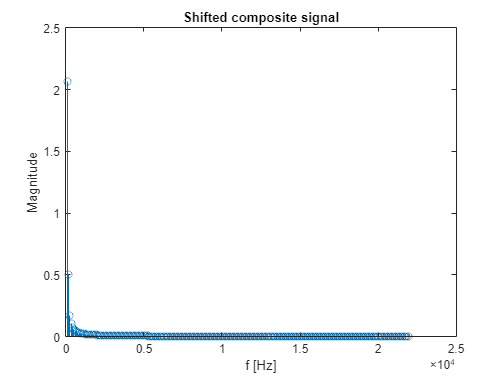

shifted_composite = fftshift(abs(composite_dft));
stem(fq, shifted_composite(257:512));
title("Shifted composite signal")
ylabel("Magnitude")
xlabel("f [Hz]")

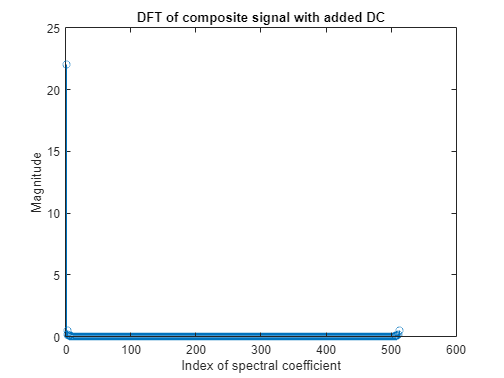

composite_dc = composite + 20;
composite_dc_dft = calculate_dft(composite_dc(1:512));
stem(abs(composite_dc_dft))
title("DFT of composite signal with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

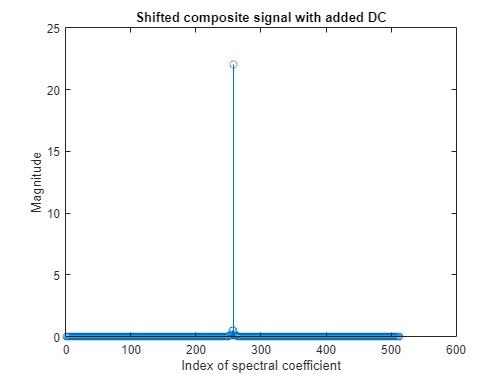

shifted_composite_dc = fftshift(abs(composite_dc_dft));
stem(shifted_composite_dc);
title("Shifted composite signal with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

**Answer: **Some tones result in the value being higher on the graph then added DC value

## Signal not abiding Nyquist theorem

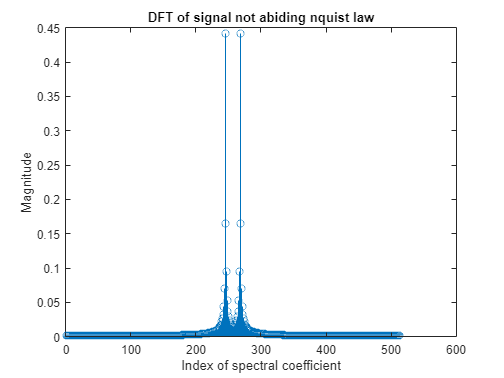

sig_broken_dft = calculate_dft(sig_broken(1:512));
stem(abs(sig_broken_dft));
title("DFT of signal not abiding nquist law")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

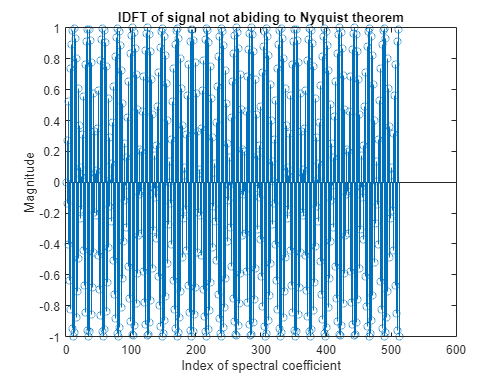

sig_broken_idft = calculate_idft(sig_broken_dft);
stem(real(sig_broken_idft));
title("IDFT of signal not abiding to Nyquist theorem")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

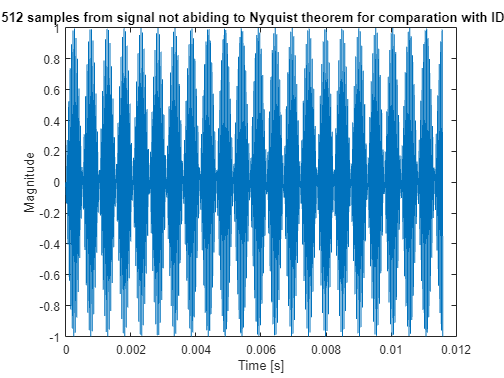

plot(time_axis(1:512), sig_broken(1:512))
title("512 samples from signal not abiding to Nyquist theorem for comparation with IDFT")
ylabel("Magnitude")
xlabel("Time [s]")

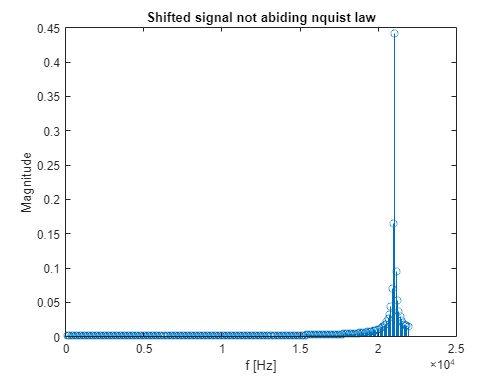

shifted_sig_broken = fftshift(abs(sig_broken_dft));
stem(fq, shifted_sig_broken(257:512));
title("Shifted signal not abiding nquist law")
ylabel("Magnitude")
xlabel("f [Hz]")

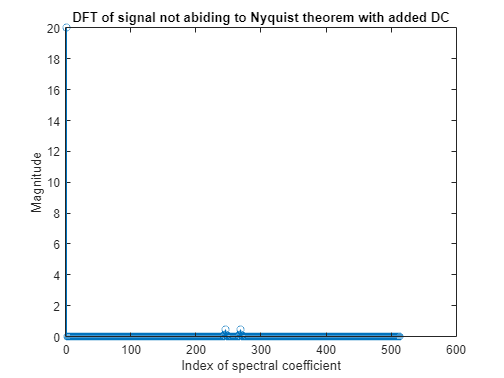

sig_broken_dc = sig_broken + 20;
sig_broken_dc_dft = calculate_dft(sig_broken_dc(1:512));
stem(abs(sig_broken_dc_dft))
title("DFT of signal not abiding to Nyquist theorem with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

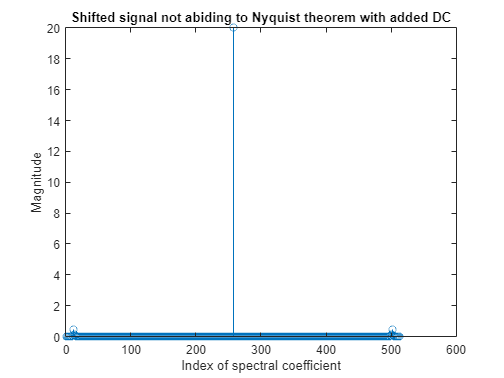

shifted_sig_broken_dc = fftshift(abs(sig_broken_dc_dft));
stem(shifted_sig_broken_dc);
title("Shifted signal not abiding to Nyquist theorem with added DC")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

## **Úloha 2 **

Vygenerujte si jednoduchý signál. Pre okienko veľkosti 512 a okienko dĺžky, ktoré nezachytí ani celú základnú periódu (je príliš krátke) vypočítajte a vizualizujte DFT. Sú výstupné spektrá zhodné? Prečo je to tak?

## **Riešenie:**

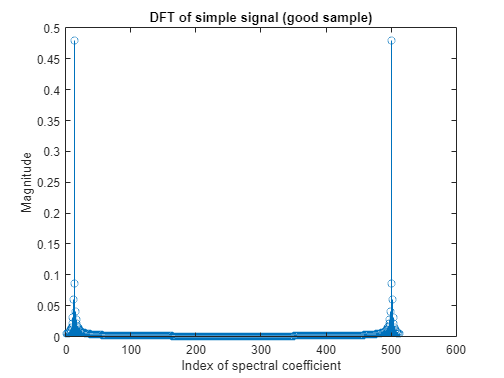

stem(abs(calculate_dft(sig_4(1:512))))
title("DFT of simple signal (good sample)")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

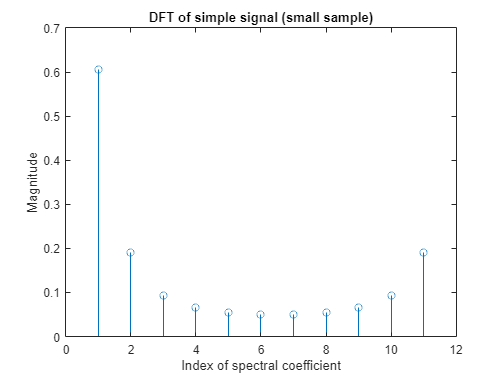

stem(abs(calculate_dft(sig_4(1:11))))
title("DFT of simple signal (small sample)")
ylabel("Magnitude")
xlabel("Index of spectral coefficient")

**Answer: **They are not the same, dft from window that captures the entire period is symetrical, dft from sample that is too small to capture a period is not symetrical

## Priestor pre vaše funkcie:

#### **Functions programmed based on formulas from lecture**

function dft = calculate_dft(in)
    M = length(in);
    dft = zeros(0,M);
    for index_u = 1:1:M
        temp_sum = 0;
        for index_x = 1:1:M
            temp_sum = temp_sum + in(index_x) * exp((-1j*2*pi*(index_u -1)*(index_x -1))/M);
        end
        dft(index_u) = 1/M * temp_sum;
    end
end

function idft = calculate_idft(in)
    M = length(in);
    idft = zeros(0,M);
    for index_u = 1:1:M
        temp_sum = 0;
        for index_x = 1:1:M
            temp_sum = temp_sum + in(index_x) * exp((1i*2*pi*(index_u -1)*(index_x -1))/M);
        end
        idft(index_u) = temp_sum;
    end 
end